# **P4.17**

In this problem we are tasked with training a simple two layer perceptron with a linear activation function in the output unit to try and approximate the function $y\left(x\right)=0\ldotp 3+0\ldotp 2\cos \left(2\pi x\right),x\in \left\lbrack 0,1\right\rbrack$.

To this end, will generate 20 samples, linearly spaced in the interval $\left\lbrack 0,1\right\rbrack$as our training set accompanied by their respective $y\left(x\right)$values in order to train the network.

We will test the following number of hidden units in the hidden layer to demonstrate the bias/variance trade-off:

- 1

- 5

- 10

The following have been assumed since they were not mentioned in the problem statement:

- Training Function: Levenberg-Marquardt

- Performance Metric: MSE

- Maximum number of epochs: 1000

- Initial Learning Rate: 0.001

x_train = linspace(0, 1, 20);
y_train = 0.3 + 0.2*cos(2*pi*x_train);
% x_test is 50 samples chosen uniformly from (0, 1)
x_test = rand([1, 50]);
y_test = 0.3 + 0.2*cos(2*pi*x_test);

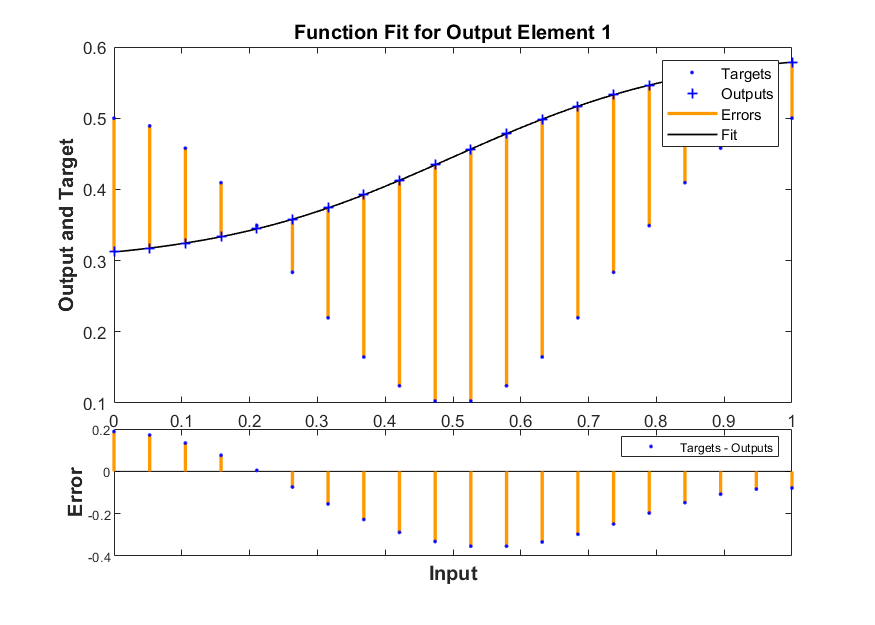

% network initialization
% we use "fitnet" which is an specialization of the feedforwardnet that
% uses the purelin activation function in its last layer.
net = fitnet(1);
% now we will train the network
% please run this script to be able to see the different plots
[net, tr] = train(net, x_train, y_train);
plotfit(net, x_train, y_train);

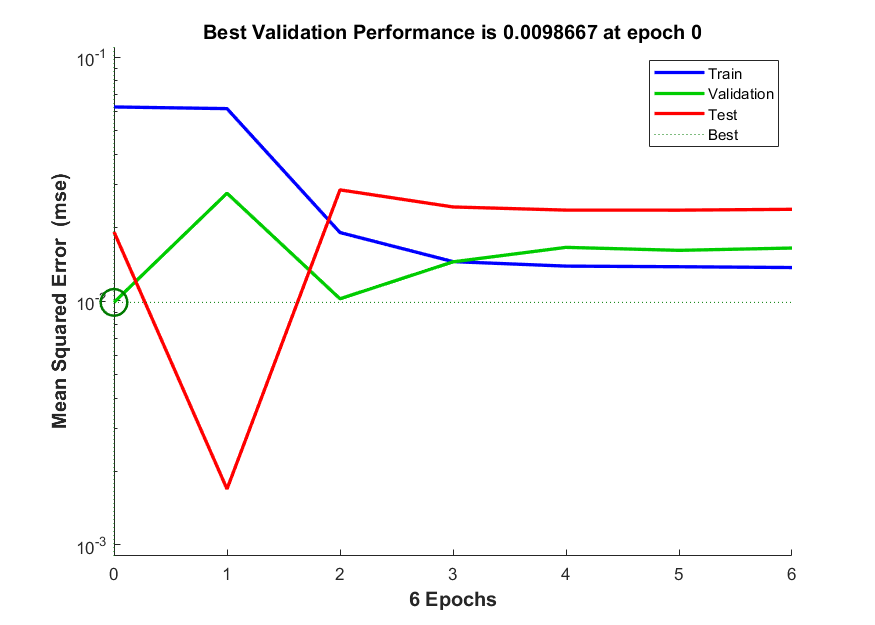

plotperform(tr);

As we can see in the generated outputs, the network simply does not have the capacity to perform desirably on the training set even after 2000 epochs. Nevertheless, we will see how the network performs on the test set.

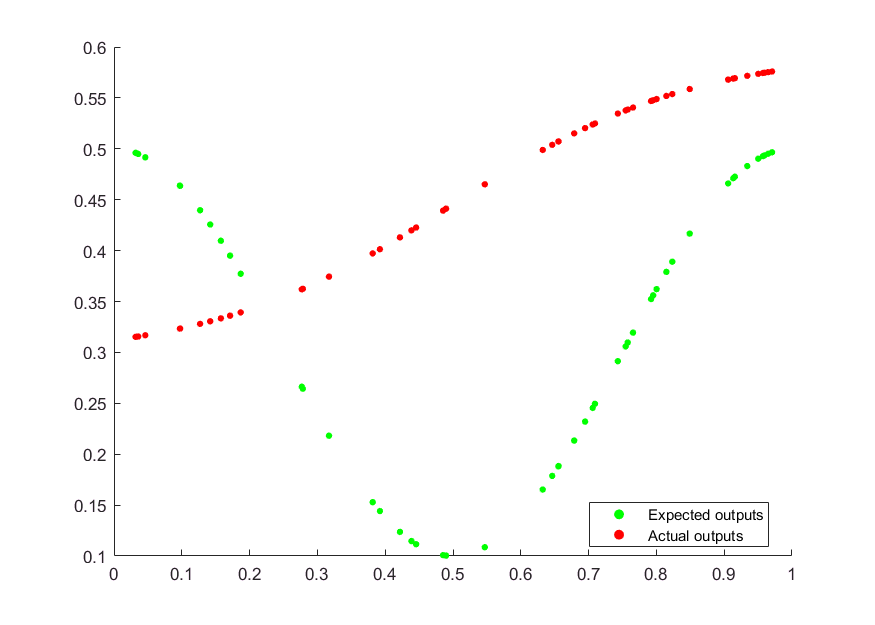

y_pred = net(x_test);
scatter(x_test, y_test, 15, 'green', 'filled');
hold on
scatter(x_test, y_pred, 15, 'red', 'filled');
legend('Expected outputs', 'Actual outputs', 'location','best');
hold off

The performance on the test set is not satisfactory either. This network is highly biased.

Now we will run the same experiment with other network sizes.

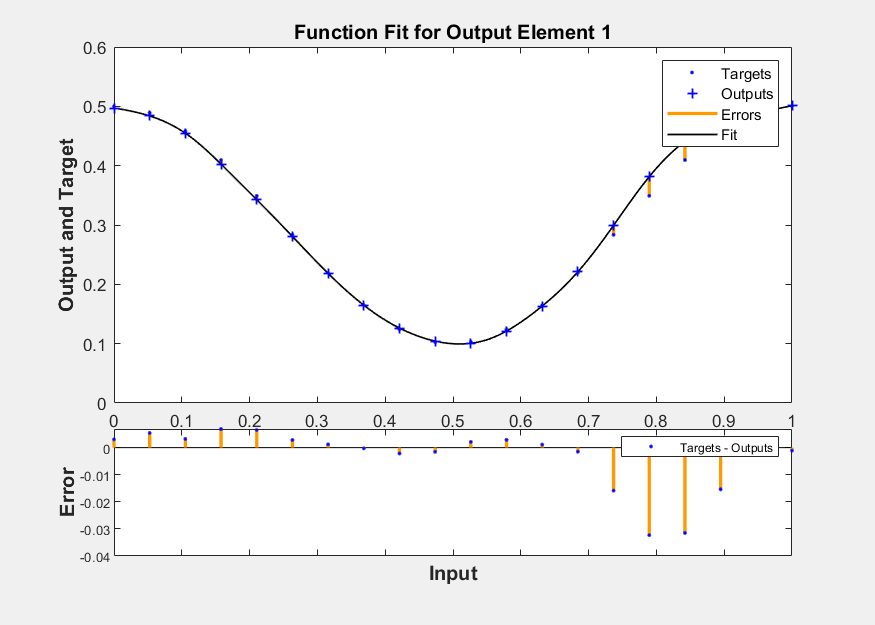

net = fitnet(5);
[net, tr] = train(net, x_train, y_train);
plotfit(net, x_train, y_train);

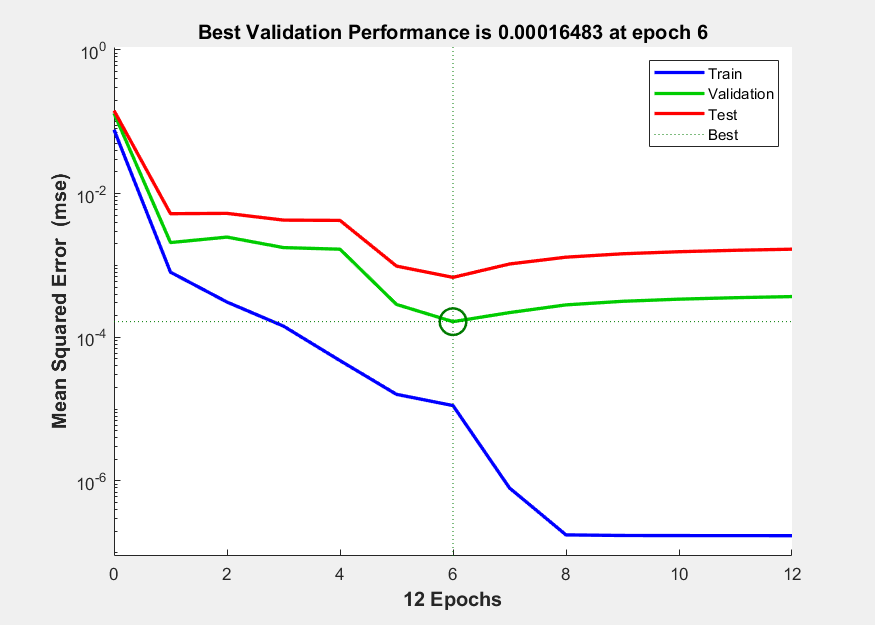

plotperform(tr);

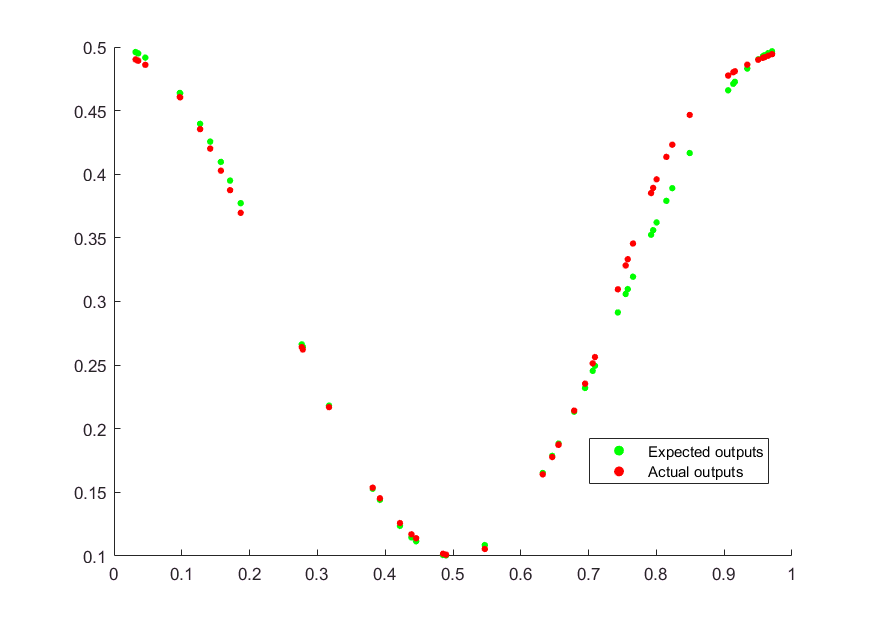

y_pred = net(x_test);
scatter(x_test, y_test, 15, 'green', 'filled');
hold on
scatter(x_test, y_pred, 15, 'red', 'filled');
legend('Expected outputs', 'Actual outputs', 'location','best');
hold off

With only 5 neurons in the hidden layer we are able to achieve a close to perfect accuracy as displayed above. This network is well adjusted.

Finally we will test a very high-capacity network for overfitting.

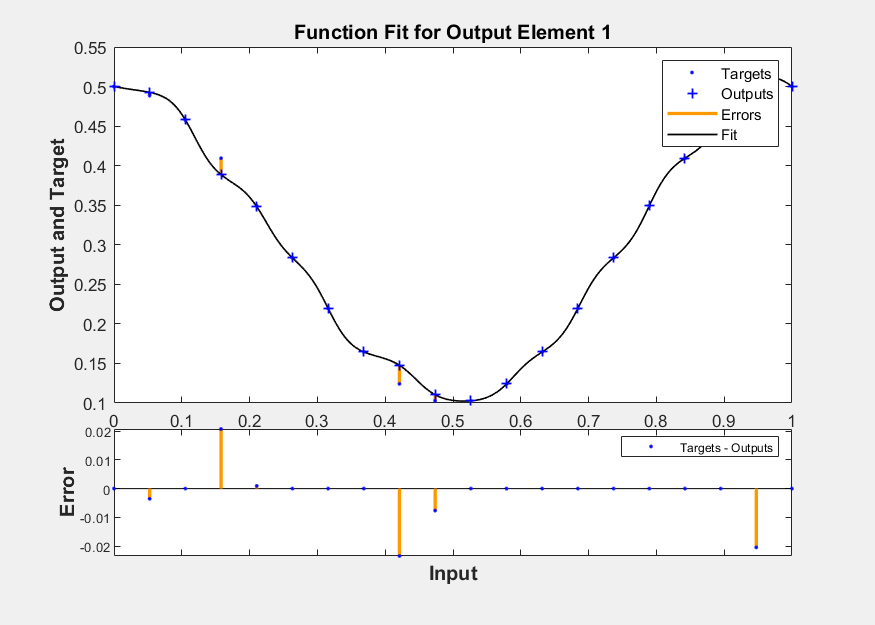

net = fitnet(10);
[net, tr] = train(net, x_train, y_train);
plotfit(net, x_train, y_train);

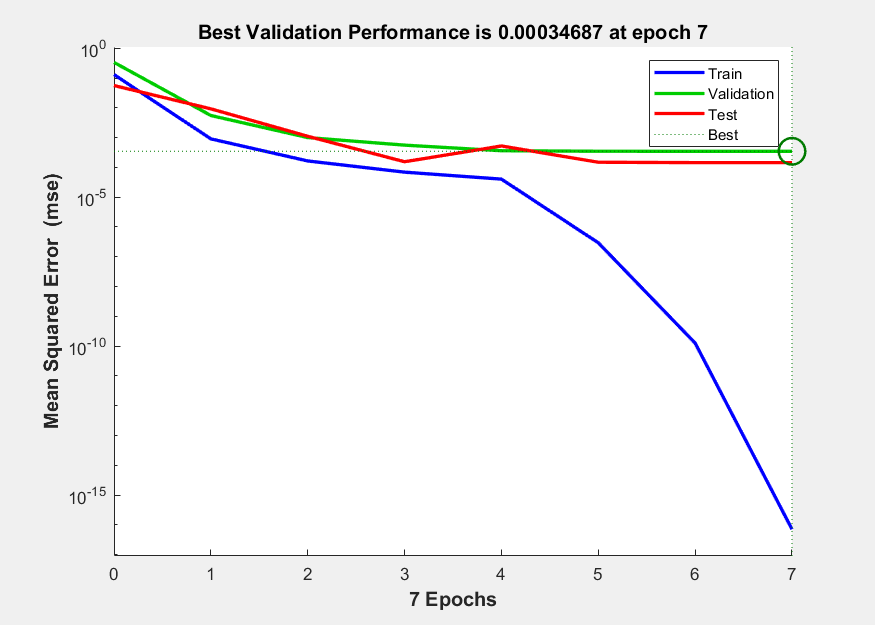

plotperform(tr);

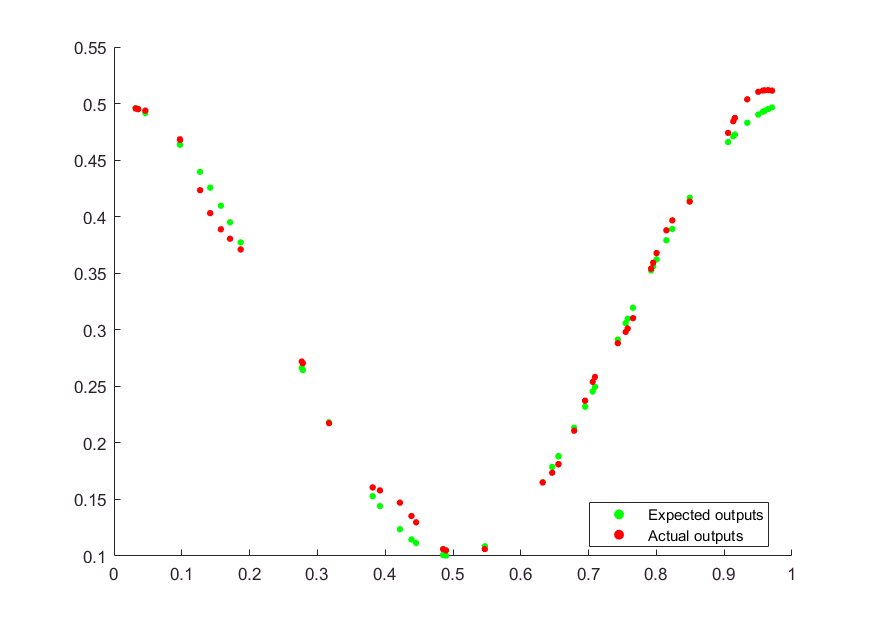

y_pred = net(x_test);
scatter(x_test, y_test, 15, 'green', 'filled');
hold on
scatter(x_test, y_pred, 15, 'red', 'filled');
legend('Expected outputs', 'Actual outputs', 'location','best');
hold off

As we can see, this network is highly variant and although it achieves a very good accuracy on the training set, its performance on the test set is less that optimal and its output does not look like a sinsoidal like in the case with 5 neurons in the hidden layer.